# Calcium transients in control and Cx26 cKO cochlea IHCs

% room temp, 6K+ ACSF, dissected at p5-p6, 16-24 hours in vitro
% tecta-cre;Cx26fl/fl;R26-GCamP3fl/+ and tecta-cre;cx26fl/+;R26-GCamP3fl/+

defaultDir = 'F:\Calvin\Spontaneous activity in GJB2\IHC ISC Calcium Imaging\6K room and phys\IHC correlation'

defaultDir = 'C:\Users\Bergles Lab\Desktop\Spontaneous activity in GJB2\IHC ISC Calcium Imaging\6K room and phys\IHC correlation'

cd(defaultDir);


% This analysis was mean IHC calcium transients with individual cell ROIs 

con1 = load('IHCcalciumCon1.mat'); % exp270
con2 = load('IHCcalciumCon2.mat'); % exp274-1-2
con3 = load('IHCcalciumCon3.mat'); % 274-3-1
con4 = load('IHCcalciumCon4.mat'); % 274-3-2
con5 = load('IHCcalciumCon5.mat'); % 282-8-2
con6 = load('IHCcalciumCon6.mat'); % 292-7-2
con7 = load('IHCcalciumCon7.mat'); % 282-8-1
con8 = load('IHCcalciumCon8.mat'); % 282-5-2, not great - some depolarized IHCs

tectacx1 = load('IHCcalciumCx261.mat'); % exp270
tectacx2 = load('IHCcalciumCx262.mat');  % 274_2_1
tectacx3 = load('IHCcalciumCx263.mat'); % 274_2_2
tectacx4 = load('IHCcalciumCx264.mat'); % 282_9_1
tectacx5 = load('IHCcalciumCx265.mat'); %282_9_2
tectacx6 = load('IHCcalciumCx266.mat'); %439_6_1
tectacx7 = load('IHCcalciumCx267.mat'); %439_1_2


% calcium event frequency - mean is per sample (52-67 ROIs averaged per sample)

controlF = [con1.meanEventFreq,con2.meanEventFreq,con3.meanEventFreq,con4.meanEventFreq,con5.meanEventFreq,con6.meanEventFreq,con7.meanEventFreq,con8.meanEventFreq]

controlF =     1.0033    1.2585    1.3363    1.2921    1.3584    1.2772    1.0372    0.9226


cx26F = [tectacx1.meanEventFreq,tectacx2.meanEventFreq,tectacx3.meanEventFreq,tectacx4.meanEventFreq,tectacx5.meanEventFreq,tectacx6.meanEventFreq,tectacx7.meanEventFreq]

cx26F =     0.9982    1.0594    1.4129    0.8106    1.4720    0.9289    0.8913



conditions = {'Control','Cx26 cKO'};
ylbl1 = 'Events per minute';
dim = [1 2];
[fig1 h p2] = compare2(controlF,cx26F,conditions,ylbl1,dim);

not normal
   0



p2

p2 = 0.4634

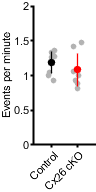

ylim([0 2]);


% calcium event width - mean
controlW = [con1.meanEventWidth,con2.meanEventWidth,con3.meanEventWidth,con4.meanEventWidth,con5.meanEventWidth,con6.meanEventWidth,con7.meanEventWidth,con8.meanEventWidth];
cx26W = [tectacx1.meanEventWidth,tectacx2.meanEventWidth,tectacx3.meanEventWidth,tectacx4.meanEventWidth,tectacx5.meanEventWidth,tectacx6.meanEventWidth,tectacx7.meanEventWidth]

cx26W =     5.4827    5.2605    5.0237    6.4024    6.1953    6.3145    6.4307


dim = [1 2];
ylbl1 = 'Duration (s)';
[fig2 h p3]= compare2(controlW,cx26W,conditions,ylbl1,dim);

     0



p3

p3 = 0.0868

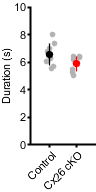

ylim([0 10]);




% num active IHC per ISC event 
controlN = [nanmean(con1.numIHCActive),nanmean(con2.numIHCActive),nanmean(con3.numIHCActive),nanmean(con4.numIHCActive),nanmean(con5.numIHCActive),nanmean(con6.numIHCActive),nanmean(con7.numIHCActive)];
cx26N = [nanmean(tectacx1.numIHCActive),nanmean(tectacx2.numIHCActive),nanmean(tectacx3.numIHCActive),nanmean(tectacx4.numIHCActive),nanmean(tectacx5.numIHCActive),nanmean(tectacx6.numIHCActive),nanmean(tectacx7.numIHCActive)];
ylbl1 = '# IHCs active per ISC event';
[fig3 h p4] = compare2(controlN,cx26N,conditions,ylbl1,dim);

     1



p4

p4 = 0.0057

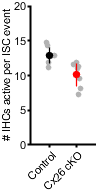

ylim([0 20]);

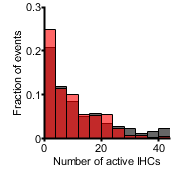


% Histogram of #s of active IHCs 
% is there a size cutoff for ISC events? 
controlN = [con1.numIHCActive,con2.numIHCActive,con3.numIHCActive,con4.numIHCActive,con5.numIHCActive,con6.numIHCActive,con7.numIHCActive];
cx26N = [tectacx1.numIHCActive,tectacx2.numIHCActive,tectacx3.numIHCActive,tectacx4.numIHCActive,tectacx5.numIHCActive,tectacx6.numIHCActive,tectacx7.numIHCActive];
figure;
binSize = [0 0.01:4:44 100];
h1 = histogram(controlN,'BinEdges',binSize);
hold on
h2 = histogram(cx26N,'BinEdges',binSize);
h1.FaceColor = 'k';
h2.FaceColor = 'r';
h1.Normalization = 'probability';
h2.Normalization = 'probability';
xlabel('Number of active IHCs');
ylabel('Fraction of events');
figQuality(gcf,gca,[1.8 1.8])
xlim([0 44])
ylim([0 0.3]);

%print(gcf,'-dpdf')

 % CDF plot
 figure
 h1 = cdfplot(controlN)

h1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [1×102 double]
              YData: [1×102 double]
              ZData: [1×0 double]

  Show all properties


 hold on
 h2 = cdfplot(cx26N)

h2 =   Line with properties:

              Color: [0.8500 0.3250 0.0980]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [-Inf 1 1 2 2 3 3 4 4 5 5 6 6 7 7 8 8 9 9 10 10 11 11 12 12 13 13 14 14 15 15 16 16 17 17 18 18 19 19 20 20 21 21 22 22 23 23 24 24 25 25 26 26 27 27 28 28 29 29 30 30 31 31 32 32 33 33 36 36 37 37 40 40 41 41 46 46 Inf]
              YData: [1×78 double]
              ZData: [1×0 double]

  Show all properties


h1.Color = 'k';
h2.Color = 'r';
h1.LineWidth = 1;
h2.LineWidth = 1;
xlabel('Number of active IHCs');
ylabel('Probability');
xlim([0 60])
figQuality(gcf,gca,[1.75 1.75])

 
 [h p] = kstest2(controlN,cx26N);
 p

p = 0.0334

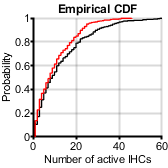

 hold off

 % ISC event size vs. # IHCs active scatter plot
 l_grey = [0.7 0.7 0.7];
 l_red = [1 0.4 0.6];
 markSize =5;
 
 % if number active IHCs < 5, set to NaN
 minHC = 4;
 
 for x = 1:length(con1.numIHCActive)
     if con1.numIHCActive(x) <=  minHC
         con1.numIHCActive(x) = NaN;
     end
 end
 for x = 1:length(con2.numIHCActive)
     if con2.numIHCActive(x) <=  minHC
         con2.numIHCActive(x) = NaN;
     end
 end
 for x = 1:length(con3.numIHCActive)
     if con3.numIHCActive(x) <=  minHC
         con3.numIHCActive(x) = NaN;
     end
 end
 for x = 1:length(con4.numIHCActive)
     if con4.numIHCActive(x) <=  minHC
         con4.numIHCActive(x) = NaN;
     end
 end
 for x = 1:length(con5.numIHCActive)
     if con5.numIHCActive(x) <=  minHC
         con5.numIHCActive(x) = NaN;
     end
 end
 for x = 1:length(con6.numIHCActive)
     if con6.numIHCActive(x) <=  minHC
         con6.numIHCActive(x) = NaN;
     end
 end
 for x = 1:length(con7.numIHCActive)
     if con7.numIHCActive(x) <=  minHC
         con7.numIHCActive(x) = NaN;
     end
 end

 for x = 1:length(tectacx1.numIHCActive)
     if tectacx1.numIHCActive(x) <=  minHC
         tectacx1.numIHCActive(x) = NaN;
     end
 end
  for x = 1:length(tectacx2.numIHCActive)
     if tectacx2.numIHCActive(x) <=  minHC
         tectacx2.numIHCActive(x) = NaN;
     end
  end
   for x = 1:length(tectacx3.numIHCActive)
     if tectacx3.numIHCActive(x) <=  minHC
         tectacx3.numIHCActive(x) = NaN;
     end
   end
    for x = 1:length(tectacx4.numIHCActive)
     if tectacx4.numIHCActive(x) <=  minHC
         tectacx4.numIHCActive(x) = NaN;
     end
    end
     for x = 1:length(tectacx5.numIHCActive)
     if tectacx5.numIHCActive(x) <=  minHC
         tectacx5.numIHCActive(x) = NaN;
     end
     end
      for x = 1:length(tectacx6.numIHCActive)
     if tectacx6.numIHCActive(x) <=  minHC
         tectacx6.numIHCActive(x) = NaN;
     end
      end
       for x = 1:length(tectacx7.numIHCActive)
     if tectacx7.numIHCActive(x) <=  minHC
         tectacx7.numIHCActive(x) = NaN;
     end
 end

 con1ISC = load('20190815 exp270 mouse 4 tecta-cre cx26fl+ gcamp3 movie 2 prep 2 1x_ISCdata.mat')

con1ISC = struct with fields:
    ISCstruct: [1×1 struct]


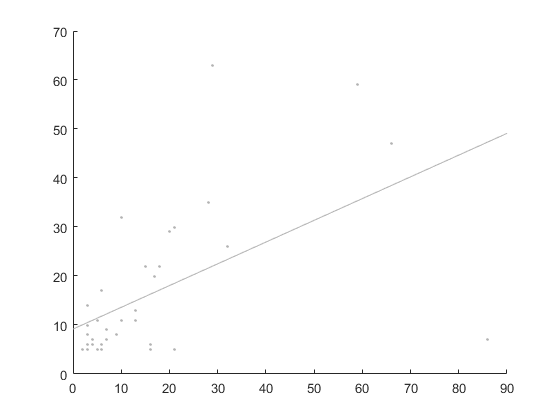

 minSC = 1;
 for x = 1:size(con1ISC.ISCstruct.event,2)
     if con1ISC.ISCstruct.event(x).area < minSC
         con1ISC.ISCstruct.event(x).area = NaN;
     end
 end
 
 figure
 scatter([con1ISC.ISCstruct.event.area],[con1.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon1 = fitlm([con1ISC.ISCstruct.event.area]',[con1.numIHCActive]');
 hLine = refline(fitcon1.Coefficients{2,1},fitcon1.Coefficients{1,1});
 hLine.Color = l_grey;
 hold off


 con2ISC = load('20190822 exp274 tecta cx26fl+ gc3 mouse 1 prep 2 movie 2 1x_ISCdata.mat')

con2ISC = struct with fields:
    ISCstruct: [1×1 struct]


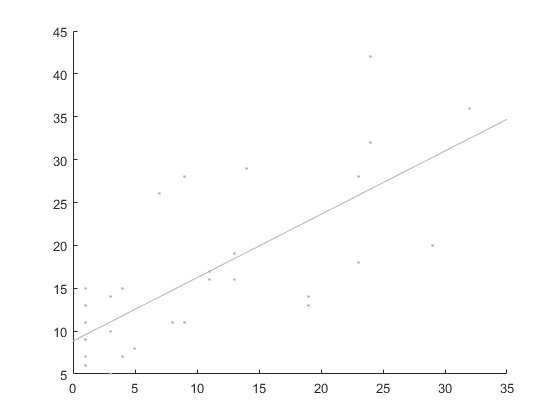

  for x = 1:size(con2ISC.ISCstruct.event,2)
     if con2ISC.ISCstruct.event(x).area < minSC
         con2ISC.ISCstruct.event(x).area = NaN;
     end
 end
 figure
 scatter([con2ISC.ISCstruct.event.area],[con2.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon2 = fitlm([con2ISC.ISCstruct.event.area]',[con2.numIHCActive]');
 hLine = refline(fitcon2.Coefficients{2,1},fitcon2.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con3ISC = load('20190822 exp274 tecta cx26fl+ gc3 mouse 3 prep 1 movie 2 1x_ISCdata.mat')

con3ISC = struct with fields:
    ISCstruct: [1×1 struct]


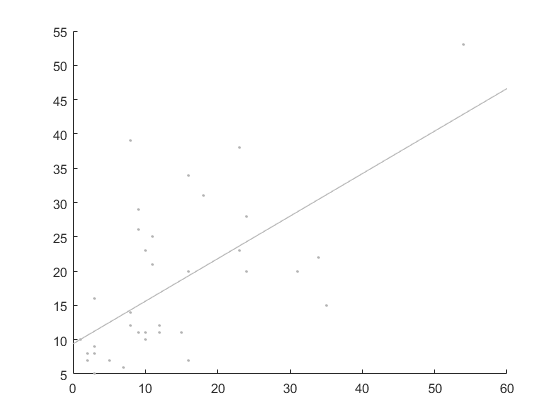

   for x = 1:size(con3ISC.ISCstruct.event,2)
     if con3ISC.ISCstruct.event(x).area < minSC
         con3ISC.ISCstruct.event(x).area = NaN;
     end
 end
 scatter([con3ISC.ISCstruct.event.area],[con3.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon3 = fitlm([con3ISC.ISCstruct.event.area]',[con3.numIHCActive]');
 hLine = refline(fitcon3.Coefficients{2,1},fitcon3.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con4ISC = load('20190822 exp274 tecta cx26fl+ gc3 mouse 3 prep 2 movie 2 1x_ISCdata.mat')

con4ISC = struct with fields:
    ISCstruct: [1×1 struct]


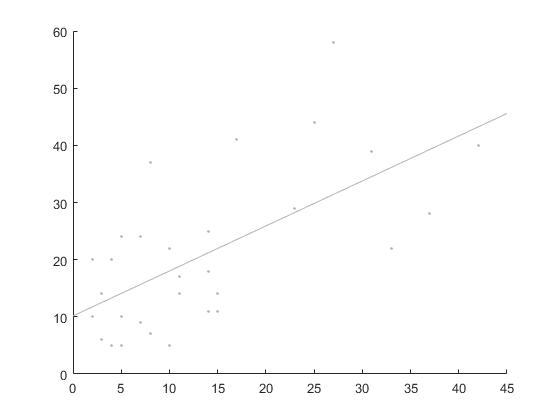

   for x = 1:size(con4ISC.ISCstruct.event,2)
     if con4ISC.ISCstruct.event(x).area < minSC
         con4ISC.ISCstruct.event(x).area = NaN;
     end
 end
 scatter([con4ISC.ISCstruct.event.area],[con4.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon4 = fitlm([con4ISC.ISCstruct.event.area]',[con4.numIHCActive]');
 hLine = refline(fitcon4.Coefficients{2,1},fitcon4.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con5ISC = load('20190918 exp282 tecta cx26 fl+ gcamp mouse 8prep 2 movie 1 1x_ISCdata.mat')

con5ISC = struct with fields:
    ISCstruct: [1×1 struct]


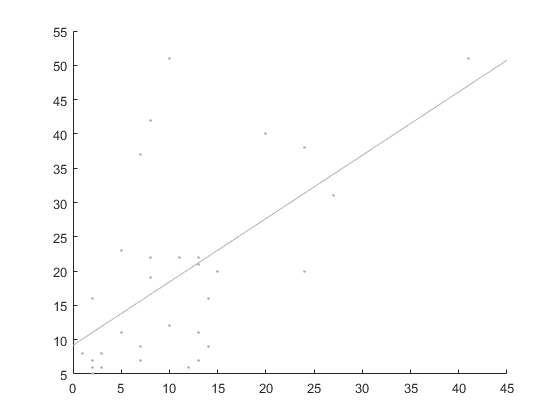

   for x = 1:size(con5ISC.ISCstruct.event,2)
     if con5ISC.ISCstruct.event(x).area < minSC
         con5ISC.ISCstruct.event(x).area = NaN;
     end
 end
 scatter([con5ISC.ISCstruct.event.area],[con5.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon5 = fitlm([con5ISC.ISCstruct.event.area]',[con5.numIHCActive]');
 hLine = refline(fitcon5.Coefficients{2,1},fitcon5.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con6ISC = load('20191023 exp 292 mouse 7 prep 2 tecta cx26 fl+ gcamp3 1x movie 1_ISCdata.mat')

con6ISC = struct with fields:
    ISCstruct: [1×1 struct]


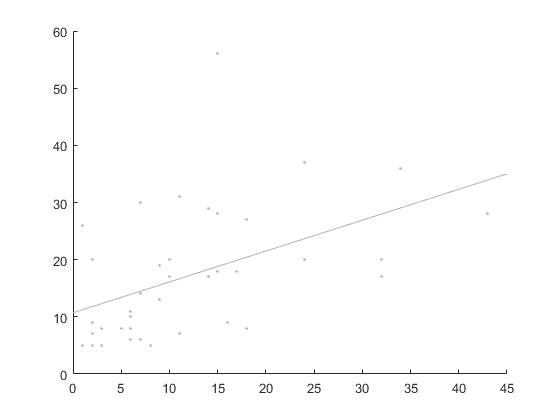

   for x = 1:size(con6ISC.ISCstruct.event,2)
     if con6ISC.ISCstruct.event(x).area < minSC
         con6ISC.ISCstruct.event(x).area = NaN;
     end
 end
 scatter([con6ISC.ISCstruct.event.area],[con6.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon6 = fitlm([con6ISC.ISCstruct.event.area]',[con6.numIHCActive]');
 hLine = refline(fitcon6.Coefficients{2,1},fitcon6.Coefficients{1,1});
 hLine.Color = l_grey;

 
 figure
 con7ISC = load('20190918 exp282 tecta cx26 fl+ gcamp mouse 8prep 1 movie 1 1x_ISCdata.mat')

con7ISC = struct with fields:
    ISCstruct: [1×1 struct]


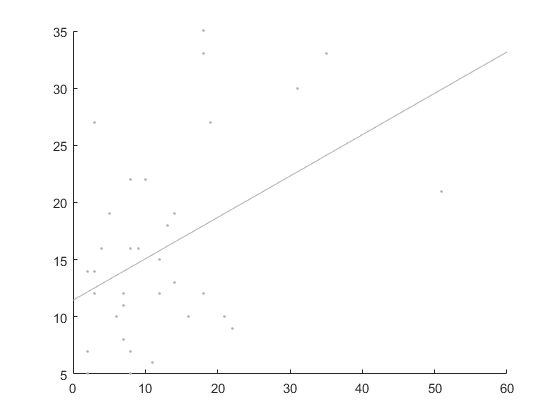

   for x = 1:size(con7ISC.ISCstruct.event,2)
     if con7ISC.ISCstruct.event(x).area < minSC
         con7ISC.ISCstruct.event(x).area = NaN;
     end
 end
 scatter([con7ISC.ISCstruct.event.area],[con7.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcon7 = fitlm([con7ISC.ISCstruct.event.area]',[con7.numIHCActive]');
 hLine = refline(fitcon7.Coefficients{2,1},fitcon7.Coefficients{1,1});
 hLine.Color = l_grey;

 
 % all data control
 ConISCarea = [[con1ISC.ISCstruct.event.area],[con2ISC.ISCstruct.event.area],[con3ISC.ISCstruct.event.area],[con4ISC.ISCstruct.event.area],[con5ISC.ISCstruct.event.area],[con6ISC.ISCstruct.event.area],[con7ISC.ISCstruct.event.area]];
 ConIHCActive = [[con1.numIHCActive],[con2.numIHCActive],[con3.numIHCActive],[con4.numIHCActive],[con5.numIHCActive],[con6.numIHCActive],[con7.numIHCActive]]

ConIHCActive =    NaN   NaN   NaN   NaN     9   NaN   NaN    47   NaN    29    11     7   NaN     8   NaN    13    11   NaN    22     5    35   NaN   NaN    22   NaN   NaN   NaN   NaN   NaN    17   NaN    11     6   NaN   NaN     5     6    32     5   NaN    20    63   NaN   NaN   NaN     7     5   NaN   NaN    30


 figure
 scatter(ConISCarea,ConIHCActive,markSize,l_grey,'filled')
  hold on
mdl = fitlm(ConISCarea',ConIHCActive');

 hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 90]
              YData: [10.5943 60.2117]
              ZData: [1×0 double]

  Show all properties


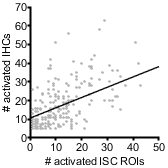

 hLine.Color = 'k';
 hLine.LineWidth = 1;
 hold off
 figQuality(gcf,gca,[1.75 1.75])
 xlim([0 50])
 xticks([0 10 20 30 40 50]);
 ylim([0 70])
 yticks([0 10 20 30 40 50 60 70])
 xlabel('# activated ISC ROIs')
 ylabel('# activated IHCs')

 
 totalnumCon = length(ConIHCActive)-sum(isnan(ConIHCActive));
 
% cKO data
 
 cko1ISC = load('20190815 exp270 mouse 3 tecta-cre cx26flfl gcamp3 movie 2 prep 1 1x_ISCdata.mat')

cko1ISC = struct with fields:
    ISCstruct: [1×1 struct]


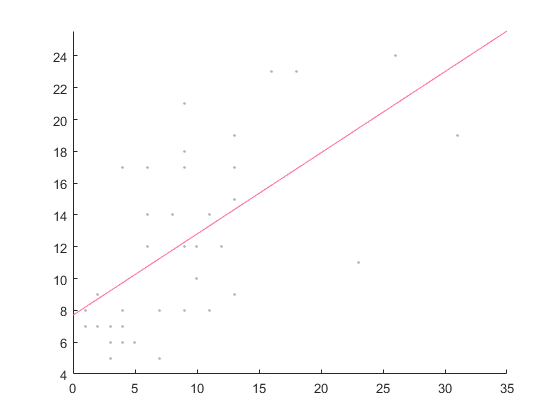

    for x = 1:size(cko1ISC.ISCstruct.event,2)
     if cko1ISC.ISCstruct.event(x).area < minSC
         cko1ISC.ISCstruct.event(x).area = NaN;
     end
 end
 figure
 scatter([cko1ISC.ISCstruct.event.area],[tectacx1.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko1 = fitlm([cko1ISC.ISCstruct.event.area]',[tectacx1.numIHCActive]');
 hLine = refline(fitcko1.Coefficients{2,1},fitcko1.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
  cko2ISC = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 1 movie 2 1x_ISCdata.mat')

cko2ISC = struct with fields:
    ISCstruct: [1×1 struct]


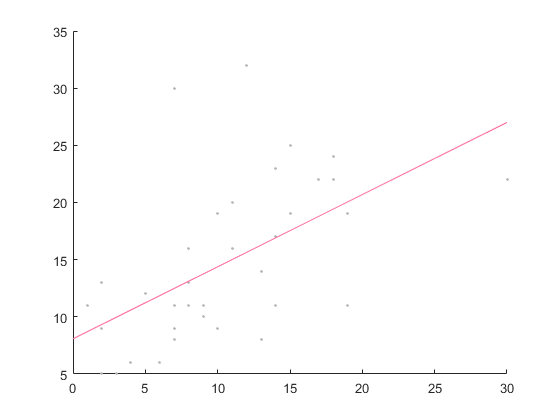

  for x = 1:size(cko2ISC.ISCstruct.event,2)
     if cko2ISC.ISCstruct.event(x).area < minSC
         cko2ISC.ISCstruct.event(x).area = NaN;
     end
 end
  figure
 scatter([cko2ISC.ISCstruct.event.area],[tectacx2.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko2 = fitlm([cko2ISC.ISCstruct.event.area]',[tectacx2.numIHCActive]');
 hLine = refline(fitcko2.Coefficients{2,1},fitcko2.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
   cko3ISC = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 2 movie 2 1x_ISCdata.mat')

cko3ISC = struct with fields:
    ISCstruct: [1×1 struct]


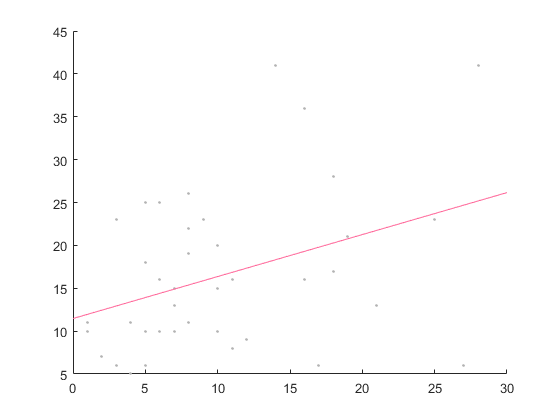

  for x = 1:size(cko3ISC.ISCstruct.event,2)
     if cko3ISC.ISCstruct.event(x).area < minSC
         cko3ISC.ISCstruct.event(x).area = NaN;
     end
 end
   figure
 scatter([cko3ISC.ISCstruct.event.area],[tectacx3.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko3 = fitlm([cko3ISC.ISCstruct.event.area]',[tectacx3.numIHCActive]');
 hLine = refline(fitcko3.Coefficients{2,1},fitcko3.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
   cko4ISC = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 1 movie 2 1x_ISCdata.mat')

cko4ISC = struct with fields:
    ISCstruct: [1×1 struct]


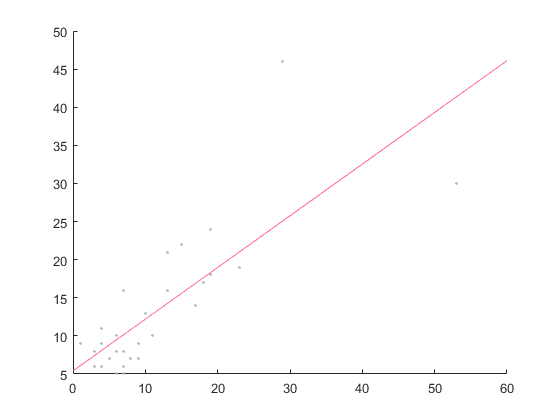

  for x = 1:size(cko4ISC.ISCstruct.event,2)
     if cko4ISC.ISCstruct.event(x).area < minSC
         cko4ISC.ISCstruct.event(x).area = NaN;
     end
 end
   figure
 scatter([cko4ISC.ISCstruct.event.area],[tectacx4.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko4 = fitlm([cko4ISC.ISCstruct.event.area]',[tectacx4.numIHCActive]');
 hLine = refline(fitcko4.Coefficients{2,1},fitcko4.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
   cko5ISC = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 2 movie 1 1x_ISCdata.mat')

cko5ISC = struct with fields:
    ISCstruct: [1×1 struct]


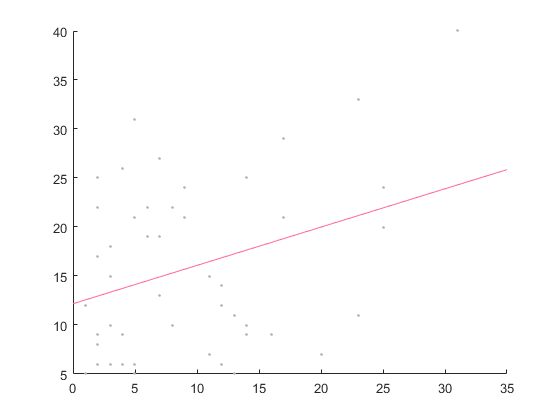

  for x = 1:size(cko5ISC.ISCstruct.event,2)
     if cko5ISC.ISCstruct.event(x).area < minSC
         cko5ISC.ISCstruct.event(x).area = NaN;
     end
 end
   figure
 scatter([cko5ISC.ISCstruct.event.area],[tectacx5.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko5 = fitlm([cko5ISC.ISCstruct.event.area]',[tectacx5.numIHCActive]');
 hLine = refline(fitcko5.Coefficients{2,1},fitcko5.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
    cko6ISC = load('20210614 exp439 mouse 6 prep 1 tecta cx26flfl gc3 movie 1 1x_ISCdata.mat')

cko6ISC = struct with fields:
    ISCstruct: [1×1 struct]


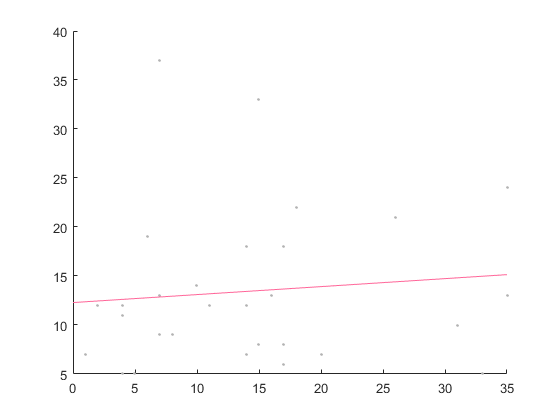

  for x = 1:size(cko6ISC.ISCstruct.event,2)
     if cko6ISC.ISCstruct.event(x).area < minSC
         cko6ISC.ISCstruct.event(x).area = NaN;
     end
 end
    figure
 scatter([cko6ISC.ISCstruct.event.area],[tectacx6.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko6 = fitlm([cko6ISC.ISCstruct.event.area]',[tectacx6.numIHCActive]');
 hLine = refline(fitcko6.Coefficients{2,1},fitcko6.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
    cko7ISC = load('20210614 exp439 mouse 1 prep 2 tecta cx26flfl gc3 movie 2 1x_ISCdata.mat')

cko7ISC = struct with fields:
    ISCstruct: [1×1 struct]


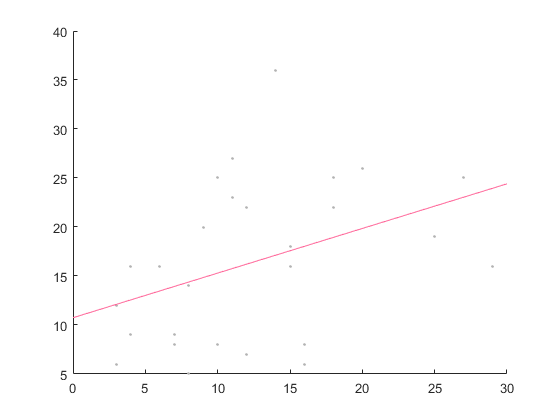

  for x = 1:size(cko7ISC.ISCstruct.event,2)
     if cko7ISC.ISCstruct.event(x).area < minSC
         cko7ISC.ISCstruct.event(x).area = NaN;
     end
 end
    figure
 scatter([cko7ISC.ISCstruct.event.area],[tectacx7.numIHCActive],markSize,l_grey,'filled')
 hold on
 fitcko7 = fitlm([cko7ISC.ISCstruct.event.area]',[tectacx7.numIHCActive]');
 hLine = refline(fitcko7.Coefficients{2,1},fitcko7.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
 % All data cKO
 CkoISCarea = [[cko1ISC.ISCstruct.event.area],[cko2ISC.ISCstruct.event.area],[cko3ISC.ISCstruct.event.area],[cko4ISC.ISCstruct.event.area],[cko5ISC.ISCstruct.event.area],[cko7ISC.ISCstruct.event.area]];
 CkoIHCActive = [[tectacx1.numIHCActive],[tectacx2.numIHCActive],[tectacx3.numIHCActive],[tectacx4.numIHCActive],[tectacx5.numIHCActive],[tectacx7.numIHCActive]]

CkoIHCActive =    NaN   NaN   NaN   NaN    14   NaN    19   NaN   NaN   NaN   NaN     6   NaN     7    12    17    17   NaN    12    24   NaN   NaN    10   NaN     8   NaN   NaN     9     8   NaN    15   NaN   NaN     7   NaN    17     6    19     8     8   NaN    23   NaN     5   NaN    23   NaN    12     8   NaN


 figure
 scatter(CkoISCarea,CkoIHCActive,markSize,l_grey,'filled')
  hold on
mdl = fitlm(CkoISCarea',CkoIHCActive');

 hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 60]
              YData: [9.3677 41.2168]
              ZData: [1×0 double]

  Show all properties


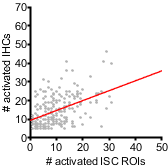

 hLine.Color = 'r';
 hLine.LineWidth = 1;
 hold off
 figQuality(gcf,gca,[1.75 1.75])
 xlim([0 50])
 xticks([0 10 20 30 40 50]);
 ylim([0 70])
 yticks([0 10 20 30 40 50 60 70])
 xlabel('# activated ISC ROIs')
 ylabel('# activated IHCs')

 
 totalnumcKO = length(CkoIHCActive)-sum(isnan(CkoIHCActive));
 

  % together control and cKO
 l_red = [213 100 124]/255;
  markSize =5;
   figure
 scatter(ConISCarea,ConIHCActive,markSize,'k','filled','MarkerFaceAlpha',0.4)
  hold on
  
 scatter(CkoISCarea,CkoIHCActive,markSize,'r','filled','MarkerFaceAlpha',0.4)
 mdl = fitlm(ConISCarea',ConIHCActive');

 hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 90]
              YData: [10.5943 60.2117]
              ZData: [1×0 double]

  Show all properties


 hLine.Color = 'k';
 hLine.LineWidth = 1;
 md2 = fitlm(CkoISCarea',CkoIHCActive');

 hLine1 = refline(md2.Coefficients{2,1},md2.Coefficients{1,1})

hLine1 =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 90]
              YData: [9.3677 57.1414]
              ZData: [1×0 double]

  Show all properties


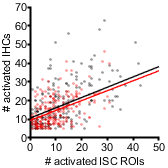

 hLine1.Color = 'r';
 hLine1.LineWidth = 1;
 meanMarkSize = 12;
%  cx26xmean = nanmean(CkoISCarea);
%  cx26ymean = nanmean(CkoIHCActive);
%  cx26ystd = nanstd(CkoIHCActive);
%  conxmean = nanmean(ConISCarea);
%  conymean = nanmean(ConIHCActive);
%  conystd = nanstd(ConIHCActive);
%  
%  errorbar([cx26xmean], cx26ymean, cx26ystd,'LineStyle', 'none','LineWidth',1,'Color','r','CapSize',0,'Marker','.','MarkerSize',meanMarkSize);
%   errorbar([conxmean], conymean, conystd,'LineStyle', 'none','LineWidth',1,'Color','k','CapSize',0,'Marker','.','MarkerSize',meanMarkSize);

  hold off
 figQuality(gcf,gca,[1.75 1.75])
 xlim([0 50])
 xticks([0 10 20 30 40 50]);
 ylim([0 70])
 yticks([0 10 20 30 40 50 60 70])
 xlabel('# activated ISC ROIs')
 ylabel('# activated IHCs')
 print(gcf,'-dpdf')

 % comparison but only non-overlapping events
  l_grey = [0.7 0.7 0.7];
 l_red = [1 0.4 0.6];
 markSize =5;
  minHC = 2;
 
 for x = 1:length(con1.numIHCActiveNoOver)
     if con1.numIHCActiveNoOver(x) <=  minHC
         con1.numIHCActiveNoOver(x) = NaN;
     end
 end
 for x = 1:length(con2.numIHCActiveNoOver)
     if con2.numIHCActiveNoOver(x) <=  minHC
         con2.numIHCActiveNoOver(x) = NaN;
     end
 end
 for x = 1:length(con3.numIHCActiveNoOver)
     if con3.numIHCActiveNoOver(x) <=  minHC
         con3.numIHCActiveNoOver(x) = NaN;
     end
 end
 for x = 1:length(con4.numIHCActiveNoOver)
     if con4.numIHCActiveNoOver(x) <=  minHC
         con4.numIHCActiveNoOver(x) = NaN;
     end
 end
 for x = 1:length(con5.numIHCActiveNoOver)
     if con5.numIHCActiveNoOver(x) <=  minHC
         con5.numIHCActiveNoOver(x) = NaN;
     end
 end
 for x = 1:length(con6.numIHCActiveNoOver)
     if con6.numIHCActiveNoOver(x) <=  minHC
         con6.numIHCActiveNoOver(x) = NaN;
     end
 end
 for x = 1:length(con7.numIHCActiveNoOver)
     if con7.numIHCActiveNoOver(x) <=  minHC
         con7.numIHCActiveNoOver(x) = NaN;
     end
 end

 for x = 1:length(tectacx1.numIHCActiveNoOver)
     if tectacx1.numIHCActiveNoOver(x) <=  minHC
         tectacx1.numIHCActiveNoOver(x) = NaN;
     end
 end
  for x = 1:length(tectacx2.numIHCActiveNoOver)
     if tectacx2.numIHCActiveNoOver(x) <=  minHC
         tectacx2.numIHCActiveNoOver(x) = NaN;
     end
  end
   for x = 1:length(tectacx3.numIHCActiveNoOver)
     if tectacx3.numIHCActiveNoOver(x) <=  minHC
         tectacx3.numIHCActiveNoOver(x) = NaN;
     end
   end
    for x = 1:length(tectacx4.numIHCActiveNoOver)
     if tectacx4.numIHCActiveNoOver(x) <=  minHC
         tectacx4.numIHCActiveNoOver(x) = NaN;
     end
    end
     for x = 1:length(tectacx5.numIHCActiveNoOver)
     if tectacx5.numIHCActiveNoOver(x) <=  minHC
         tectacx5.numIHCActiveNoOver(x) = NaN;
     end
     end
      for x = 1:length(tectacx6.numIHCActiveNoOver)
     if tectacx6.numIHCActiveNoOver(x) <=  minHC
         tectacx6.numIHCActiveNoOver(x) = NaN;
     end
      end
       for x = 1:length(tectacx7.numIHCActiveNoOver)
     if tectacx7.numIHCActiveNoOver(x) <=  minHC
         tectacx7.numIHCActiveNoOver(x) = NaN;
     end
 end

 con1ISC = load('20190815 exp270 mouse 4 tecta-cre cx26fl+ gcamp3 movie 2 prep 2 1x_ISCdata.mat')

con1ISC = struct with fields:
    ISCstruct: [1×1 struct]


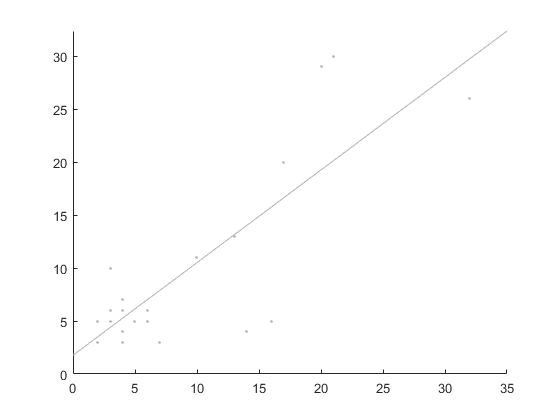

 
 figure
 scatter([con1ISC.ISCstruct.event.area],[con1.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon1 = fitlm([con1ISC.ISCstruct.event.area]',[con1.numIHCActiveNoOver]');
 hLine = refline(fitcon1.Coefficients{2,1},fitcon1.Coefficients{1,1});
 hLine.Color = l_grey;
 hold off


 con2ISC = load('20190822 exp274 tecta cx26fl+ gc3 mouse 1 prep 2 movie 2 1x_ISCdata.mat')

con2ISC = struct with fields:
    ISCstruct: [1×1 struct]


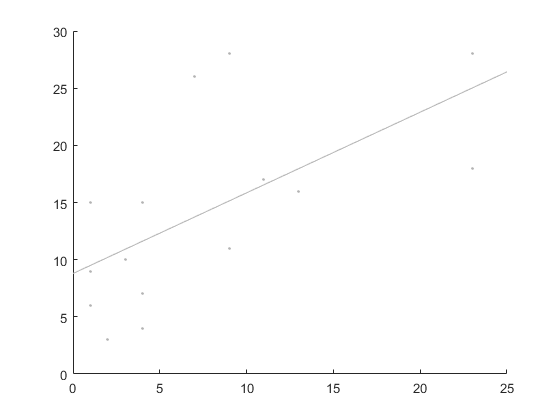

 figure
 scatter([con2ISC.ISCstruct.event.area],[con2.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon2 = fitlm([con2ISC.ISCstruct.event.area]',[con2.numIHCActiveNoOver]');
 hLine = refline(fitcon2.Coefficients{2,1},fitcon2.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con3ISC = load('20190822 exp274 tecta cx26fl+ gc3 mouse 3 prep 1 movie 2 1x_ISCdata.mat')

con3ISC = struct with fields:
    ISCstruct: [1×1 struct]


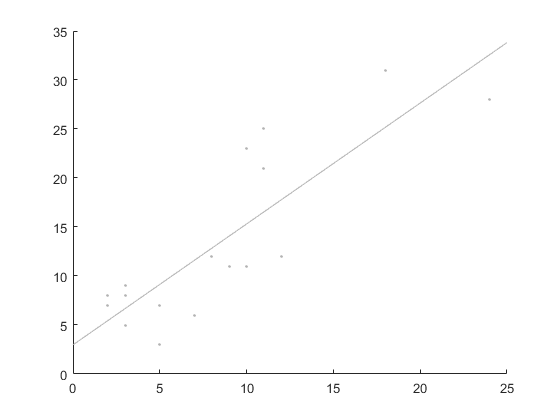

  scatter([con3ISC.ISCstruct.event.area],[con3.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon3 = fitlm([con3ISC.ISCstruct.event.area]',[con3.numIHCActiveNoOver]');
 hLine = refline(fitcon3.Coefficients{2,1},fitcon3.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con4ISC = load('20190822 exp274 tecta cx26fl+ gc3 mouse 3 prep 2 movie 2 1x_ISCdata.mat')

con4ISC = struct with fields:
    ISCstruct: [1×1 struct]


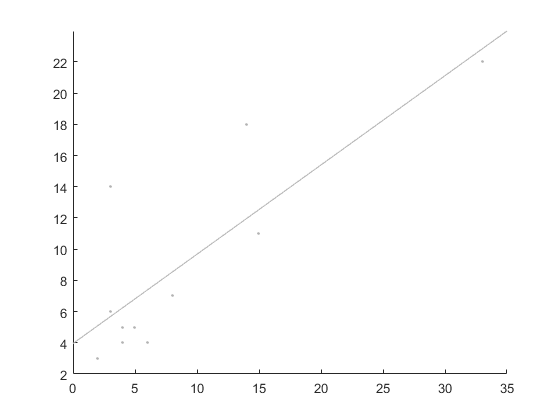

  scatter([con4ISC.ISCstruct.event.area],[con4.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon4 = fitlm([con4ISC.ISCstruct.event.area]',[con4.numIHCActiveNoOver]');
 hLine = refline(fitcon4.Coefficients{2,1},fitcon4.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con5ISC = load('20190918 exp282 tecta cx26 fl+ gcamp mouse 8prep 2 movie 1 1x_ISCdata.mat')

con5ISC = struct with fields:
    ISCstruct: [1×1 struct]


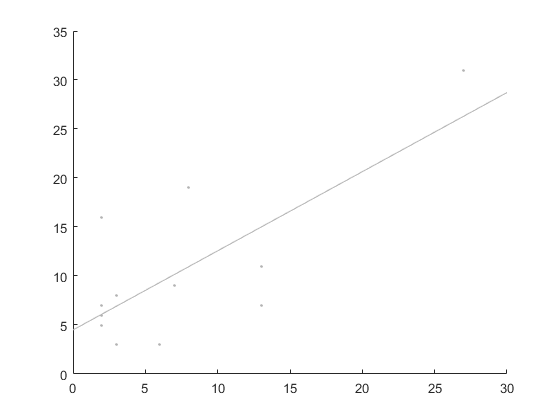

  scatter([con5ISC.ISCstruct.event.area],[con5.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon5 = fitlm([con5ISC.ISCstruct.event.area]',[con5.numIHCActiveNoOver]');
 hLine = refline(fitcon5.Coefficients{2,1},fitcon5.Coefficients{1,1});
 hLine.Color = l_grey;

 
figure
 con6ISC = load('20191023 exp 292 mouse 7 prep 2 tecta cx26 fl+ gcamp3 1x movie 1_ISCdata.mat')

con6ISC = struct with fields:
    ISCstruct: [1×1 struct]


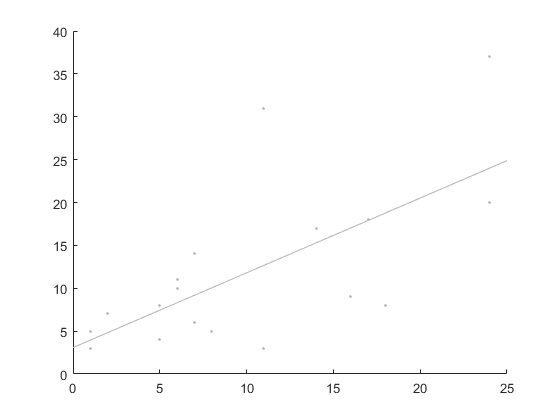

  scatter([con6ISC.ISCstruct.event.area],[con6.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon6 = fitlm([con6ISC.ISCstruct.event.area]',[con6.numIHCActiveNoOver]');
 hLine = refline(fitcon6.Coefficients{2,1},fitcon6.Coefficients{1,1});
 hLine.Color = l_grey;

 
 figure
 con7ISC = load('20190918 exp282 tecta cx26 fl+ gcamp mouse 8prep 1 movie 1 1x_ISCdata.mat')

con7ISC = struct with fields:
    ISCstruct: [1×1 struct]


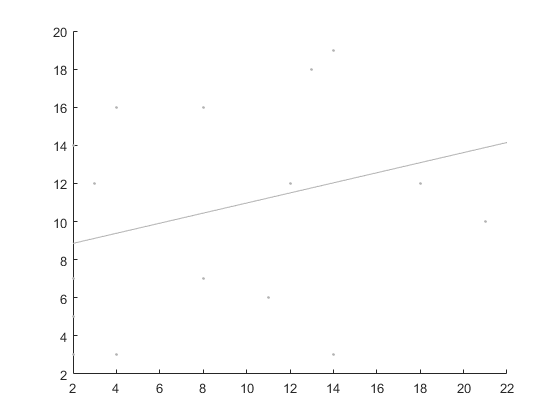

  scatter([con7ISC.ISCstruct.event.area],[con7.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcon7 = fitlm([con7ISC.ISCstruct.event.area]',[con7.numIHCActiveNoOver]');
 hLine = refline(fitcon7.Coefficients{2,1},fitcon7.Coefficients{1,1});
 hLine.Color = l_grey;

 
 % all data control
 ConISCarea = [[con1ISC.ISCstruct.event.area],[con2ISC.ISCstruct.event.area],[con3ISC.ISCstruct.event.area],[con4ISC.ISCstruct.event.area],[con5ISC.ISCstruct.event.area],[con6ISC.ISCstruct.event.area],[con7ISC.ISCstruct.event.area]];
 ConIHCActive = [[con1.numIHCActiveNoOver],[con2.numIHCActiveNoOver],[con3.numIHCActiveNoOver],[con4.numIHCActiveNoOver],[con5.numIHCActiveNoOver],[con6.numIHCActiveNoOver],[con7.numIHCActiveNoOver]]

ConIHCActive =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN    29   NaN   NaN   NaN   NaN   NaN    13   NaN   NaN   NaN     5   NaN   NaN   NaN   NaN   NaN   NaN     4     3   NaN   NaN   NaN    11     6     3     4     5     6   NaN   NaN   NaN    20   NaN   NaN   NaN   NaN     7     5   NaN   NaN    30


 figure
 scatter(ConISCarea,ConIHCActive,markSize,l_grey,'filled')
  hold on
mdl = fitlm(ConISCarea',ConIHCActive');

hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 35]
              YData: [4.6918 31.1970]
              ZData: [1×0 double]

  Show all properties


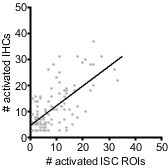

hLine.Color = 'k';
hLine.LineWidth = 1;
 hold off
 figQuality(gcf,gca,[1.75 1.75])
 xlim([0 50])
 xticks([0 10 20 30 40 50]);
 ylim([0 50])
 yticks([0 10 20 30 40 50 60 70])
 xlabel('# activated ISC ROIs')
 ylabel('# activated IHCs')

 % cKO data
   l_grey = [0.7 0.7 0.7];
 l_red = [1 0.4 0.6];
 markSize =5;
 cko1ISC = load('20190815 exp270 mouse 3 tecta-cre cx26flfl gcamp3 movie 2 prep 1 1x_ISCdata.mat')

cko1ISC = struct with fields:
    ISCstruct: [1×1 struct]


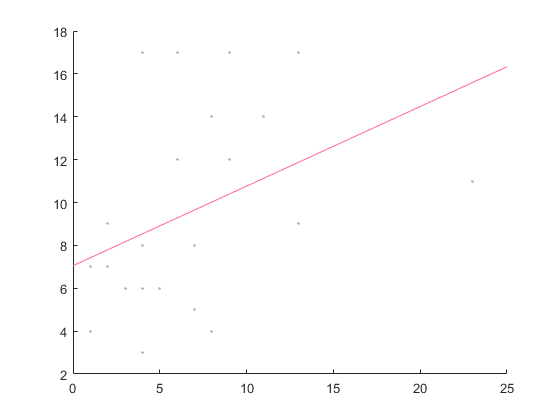

 figure
 scatter([cko1ISC.ISCstruct.event.area],[tectacx1.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko1 = fitlm([cko1ISC.ISCstruct.event.area]',[tectacx1.numIHCActiveNoOver]');
 hLine = refline(fitcko1.Coefficients{2,1},fitcko1.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
  cko2ISC = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 1 movie 2 1x_ISCdata.mat')

cko2ISC = struct with fields:
    ISCstruct: [1×1 struct]


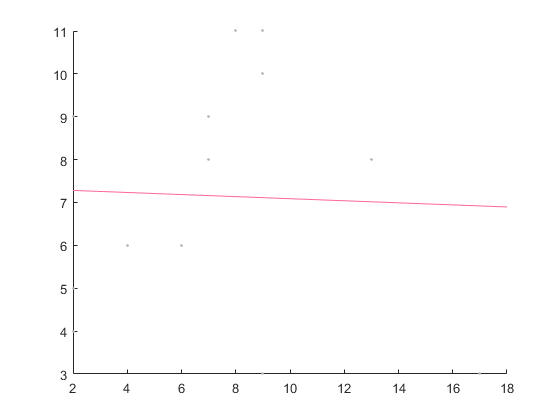

 figure
 scatter([cko2ISC.ISCstruct.event.area],[tectacx2.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko2 = fitlm([cko2ISC.ISCstruct.event.area]',[tectacx2.numIHCActiveNoOver]');
 hLine = refline(fitcko2.Coefficients{2,1},fitcko2.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
   cko3ISC = load('20190822 exp274 tecta cx26flfl gc3 mouse 2 prep 2 movie 2 1x_ISCdata.mat')

cko3ISC = struct with fields:
    ISCstruct: [1×1 struct]


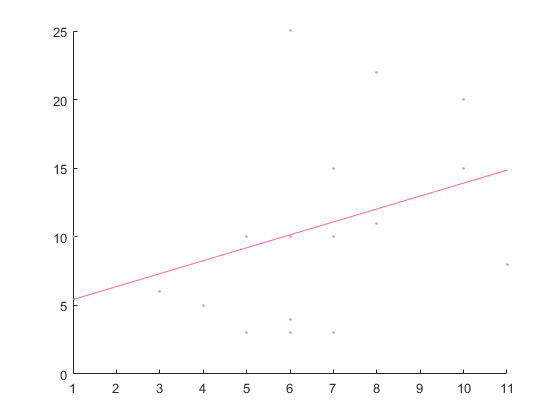

 figure
 scatter([cko3ISC.ISCstruct.event.area],[tectacx3.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko3 = fitlm([cko3ISC.ISCstruct.event.area]',[tectacx3.numIHCActiveNoOver]');
 hLine = refline(fitcko3.Coefficients{2,1},fitcko3.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
   cko4ISC = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 1 movie 2 1x_ISCdata.mat')

cko4ISC = struct with fields:
    ISCstruct: [1×1 struct]


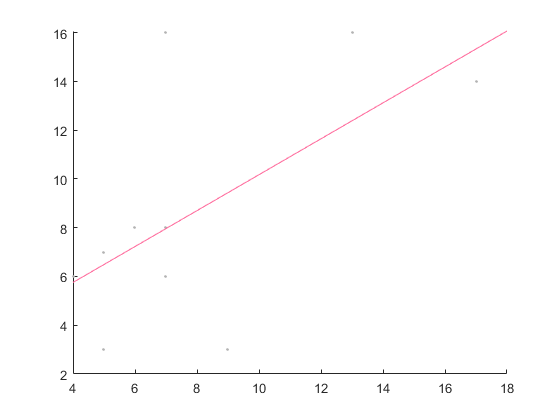

 figure
 scatter([cko4ISC.ISCstruct.event.area],[tectacx4.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko4 = fitlm([cko4ISC.ISCstruct.event.area]',[tectacx4.numIHCActiveNoOver]');
 hLine = refline(fitcko4.Coefficients{2,1},fitcko4.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
   cko5ISC = load('20190918 exp282 tecta cx26 flfl gcamp mouse 9 prep 2 movie 1 1x_ISCdata.mat')

cko5ISC = struct with fields:
    ISCstruct: [1×1 struct]


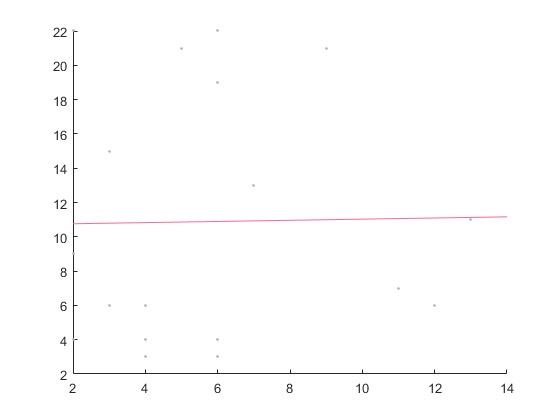

 figure
 scatter([cko5ISC.ISCstruct.event.area],[tectacx5.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko5 = fitlm([cko5ISC.ISCstruct.event.area]',[tectacx5.numIHCActiveNoOver]');
 hLine = refline(fitcko5.Coefficients{2,1},fitcko5.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
    cko6ISC = load('20210614 exp439 mouse 6 prep 1 tecta cx26flfl gc3 movie 1 1x_ISCdata.mat')

cko6ISC = struct with fields:
    ISCstruct: [1×1 struct]


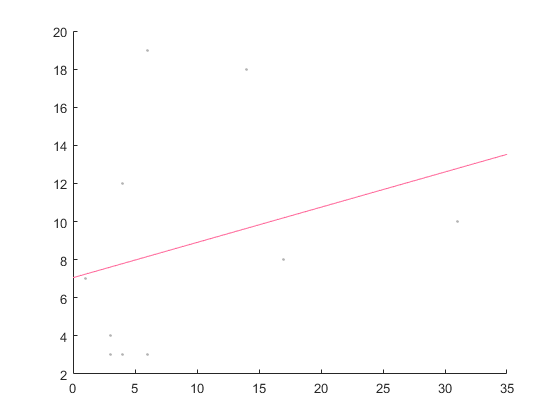

 figure
 scatter([cko6ISC.ISCstruct.event.area],[tectacx6.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko6 = fitlm([cko6ISC.ISCstruct.event.area]',[tectacx6.numIHCActiveNoOver]');
 hLine = refline(fitcko6.Coefficients{2,1},fitcko6.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
    cko7ISC = load('20210614 exp439 mouse 1 prep 2 tecta cx26flfl gc3 movie 2 1x_ISCdata.mat')

cko7ISC = struct with fields:
    ISCstruct: [1×1 struct]


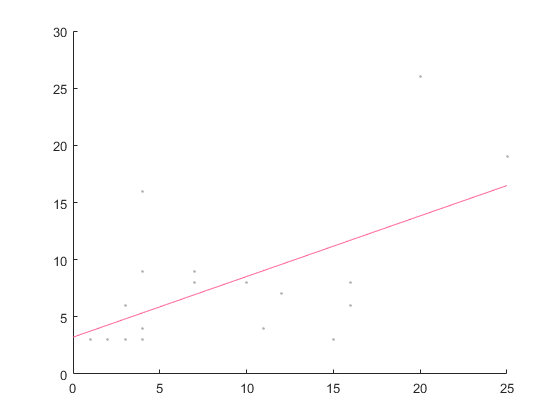

 figure
 scatter([cko7ISC.ISCstruct.event.area],[tectacx7.numIHCActiveNoOver],markSize,l_grey,'filled')
 hold on
 fitcko7 = fitlm([cko7ISC.ISCstruct.event.area]',[tectacx7.numIHCActiveNoOver]');
 hLine = refline(fitcko7.Coefficients{2,1},fitcko7.Coefficients{1,1});
 hLine.Color = l_red;
 hold off

 
 % All data cKO
 CkoISCarea = [[cko1ISC.ISCstruct.event.area],[cko2ISC.ISCstruct.event.area],[cko3ISC.ISCstruct.event.area],[cko4ISC.ISCstruct.event.area],[cko5ISC.ISCstruct.event.area],[cko6ISC.ISCstruct.event.area],[cko7ISC.ISCstruct.event.area]];
 CkoIHCActive = [[tectacx1.numIHCActiveNoOver],[tectacx2.numIHCActiveNoOver],[tectacx3.numIHCActiveNoOver],[tectacx4.numIHCActiveNoOver],[tectacx5.numIHCActiveNoOver],[tectacx6.numIHCActiveNoOver],[tectacx7.numIHCActiveNoOver]]

CkoIHCActive =    NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     6     4     7    12    17   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN   NaN     9     8   NaN   NaN   NaN     3   NaN   NaN    17     6   NaN   NaN   NaN   NaN   NaN   NaN     5   NaN   NaN   NaN    12     8   NaN


 figure
 scatter(CkoISCarea,CkoIHCActive,markSize,l_red,'filled')
  hold on
mdl = fitlm(CkoISCarea',CkoIHCActive');

 hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 35]
              YData: [7.1002 17.3487]
              ZData: [1×0 double]

  Show all properties


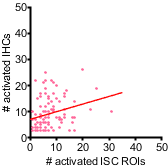

 hLine.Color = 'r';
 hLine.LineWidth = 1;
 hold off
 figQuality(gcf,gca,[1.75 1.75])
 xlim([0 50])
 xticks([0 10 20 30 40 50]);
 ylim([0 50])
 yticks([0 10 20 30 40 50 60 70])
 xlabel('# activated ISC ROIs')
 ylabel('# activated IHCs')

 % together control and cKO
 l_red = [213 100 124]/255;
  markSize =8;
  figure
 scatter(ConISCarea,ConIHCActive,markSize,l_grey,'filled')
  hold on
  mdl = fitlm(ConISCarea',ConIHCActive');

hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 35]
              YData: [4.6918 31.1970]
              ZData: [1×0 double]

  Show all properties


hLine.Color = 'k';
hLine.LineWidth = 1;
 scatter(CkoISCarea,CkoIHCActive,markSize,l_red,'filled')
   mdl = fitlm(CkoISCarea',CkoIHCActive');

 hLine = refline(mdl.Coefficients{2,1},mdl.Coefficients{1,1})

hLine =   Line with properties:

              Color: [0 0.4470 0.7410]
          LineStyle: '-'
          LineWidth: 0.5000
             Marker: 'none'
         MarkerSize: 6
    MarkerFaceColor: 'none'
              XData: [0 35]
              YData: [7.1002 17.3487]
              ZData: [1×0 double]

  Show all properties


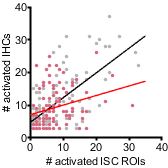

 hLine.Color = 'r';
 hLine.LineWidth = 1;
  hold off
 figQuality(gcf,gca,[1.75 1.75])
 xlim([0 40])
 xticks([0 10 20 30 40 50]);
 ylim([0 40])
 yticks([0 10 20 30 40 50 60 70])
 xlabel('# activated ISC ROIs')
 ylabel('# activated IHCs')

% mean amplitude 

controlAmp = [con1.meanEventAmp,con2.meanEventAmp,con3.meanEventAmp,con4.meanEventAmp,con5.meanEventAmp,con6.meanEventAmp,con7.meanEventAmp,con8.meanEventAmp]*100

controlAmp =   113.4705   65.5132   96.9504   96.8520   82.7826  100.7460   96.1657   72.1525


cx26Amp = [tectacx1.meanEventAmp,tectacx2.meanEventAmp,tectacx3.meanEventAmp,tectacx4.meanEventAmp,tectacx5.meanEventAmp,tectacx6.meanEventAmp,tectacx7.meanEventAmp]*100

cx26Amp =    71.3043   74.7171   97.1543   61.1790   82.8896   50.4248   58.5920


ylbl1 = 'Mean amplitude (%dF/F)';
[fig4 h p1] = compare2(controlAmp,cx26Amp,conditions,ylbl1,dim);

     1



p1

p1 = 0.0324

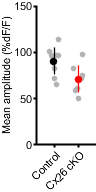

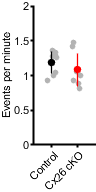

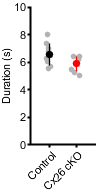

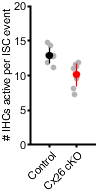


ylim([0 150]);

subP = handleTheSubplot({fig1,fig2,fig3,fig4},[1 4]);

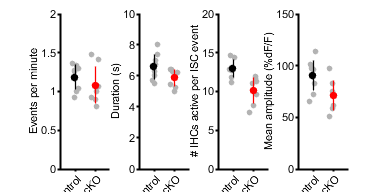

figQuality(subP,gca,[4 2])


[CorrP CorrA h] = fdr_BH([p1,p2,p3,p4],0.05)

CorrP =     0.0648    0.4634    0.1158    0.0228


CorrA =     0.0250    0.0500    0.0375    0.0125


h = 4×1 logical array
   0
   0
   0
   1


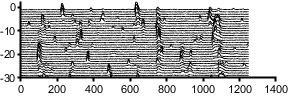

% representative raster plots

[x,n] = size(con1.ROIdF);
t = 1250;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(con1.ROIdF(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])

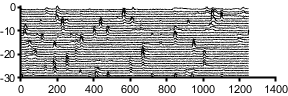


[x,n] = size(tectacx2.ROIdF);
t = 1250;
numToShow = 30;
temp = randperm(n)';
temp = sort(temp(1:numToShow));
figure; plot(tectacx2.ROIdF(:,temp) - 1*repmat(1:numToShow,t,1),'Color','k');
figQuality(gcf,gca,[3 1])



% Correlation - 4 cells away on either side, mean
controlCorr = [con1.meanIHCCorr4,con2.meanIHCCorr4,con3.meanIHCCorr4,con4.meanIHCCorr4,con5.meanIHCCorr4,con6.meanIHCCorr4];
cx26Corr = [tectacx1.meanIHCCorr4,tectacx2.meanIHCCorr4,tectacx3.meanIHCCorr4,tectacx4.meanIHCCorr4,tectacx5.meanIHCCorr4];
figure
conditions = {'Tecta-Cre;Cx26fl+','Tecta-Cre;Cx26flfl'};
ylbl1 = 'Mean Corr Coeff';
dim = [1 2];
compare2(controlCorr,cx26Corr,conditions,ylbl1,dim);

not normal
   1



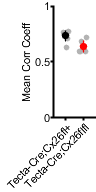

ylim([0 1]);


% Correlation - 8 cells away on either side, mean
controlCorr = [con1.meanIHCCorr8,con2.meanIHCCorr8,con3.meanIHCCorr8,con4.meanIHCCorr8,con5.meanIHCCorr8,con6.meanIHCCorr8];
cx26Corr = [tectacx1.meanIHCCorr8,tectacx2.meanIHCCorr8,tectacx3.meanIHCCorr8,tectacx4.meanIHCCorr8,tectacx5.meanIHCCorr8];
figure
conditions = {'Tecta-Cre;Cx26fl+','Tecta-Cre;Cx26flfl'};
ylbl1 = 'Mean Corr Coeff';
dim = [1.5 3];
compare2(controlCorr,cx26Corr,conditions,ylbl1,dim);

not normal
   0



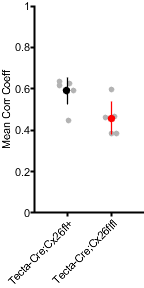

ylim([0 1]);

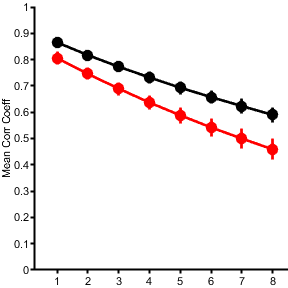



% correlation - 1-8 cells away comparing control and KO, means across all
% ie, 1-8 is mean of corr coefficient from 1-8 across all cells
controlCorr1 = [con1.meanIHCCorr1,con2.meanIHCCorr1,con3.meanIHCCorr1,con4.meanIHCCorr1,con5.meanIHCCorr1,con6.meanIHCCorr1];
controlCorr2 = [con1.meanIHCCorr2,con2.meanIHCCorr2,con3.meanIHCCorr2,con4.meanIHCCorr2,con5.meanIHCCorr2,con6.meanIHCCorr2];
controlCorr3 = [con1.meanIHCCorr3,con2.meanIHCCorr3,con3.meanIHCCorr3,con4.meanIHCCorr3,con5.meanIHCCorr3,con6.meanIHCCorr3];
controlCorr4 = [con1.meanIHCCorr4,con2.meanIHCCorr4,con3.meanIHCCorr4,con4.meanIHCCorr4,con5.meanIHCCorr4,con6.meanIHCCorr4];
controlCorr5 = [con1.meanIHCCorr5,con2.meanIHCCorr5,con3.meanIHCCorr5,con4.meanIHCCorr5,con5.meanIHCCorr5,con6.meanIHCCorr5];
controlCorr6 = [con1.meanIHCCorr6,con2.meanIHCCorr6,con3.meanIHCCorr6,con4.meanIHCCorr6,con5.meanIHCCorr6,con6.meanIHCCorr6];
controlCorr7 = [con1.meanIHCCorr7,con2.meanIHCCorr7,con3.meanIHCCorr7,con4.meanIHCCorr7,con5.meanIHCCorr7,con6.meanIHCCorr7];
controlCorr8 = [con1.meanIHCCorr8,con2.meanIHCCorr8,con3.meanIHCCorr8,con4.meanIHCCorr8,con5.meanIHCCorr8,con6.meanIHCCorr8];

cx26Corr1 = [tectacx1.meanIHCCorr1,tectacx2.meanIHCCorr1,tectacx3.meanIHCCorr1,tectacx4.meanIHCCorr1,tectacx5.meanIHCCorr1];
cx26Corr2 = [tectacx1.meanIHCCorr2,tectacx2.meanIHCCorr2,tectacx3.meanIHCCorr2,tectacx4.meanIHCCorr2,tectacx5.meanIHCCorr2];
cx26Corr3 = [tectacx1.meanIHCCorr3,tectacx2.meanIHCCorr3,tectacx3.meanIHCCorr3,tectacx4.meanIHCCorr3,tectacx5.meanIHCCorr3];
cx26Corr4 = [tectacx1.meanIHCCorr4,tectacx2.meanIHCCorr4,tectacx3.meanIHCCorr4,tectacx4.meanIHCCorr4,tectacx5.meanIHCCorr4];
cx26Corr5 = [tectacx1.meanIHCCorr5,tectacx2.meanIHCCorr5,tectacx3.meanIHCCorr5,tectacx4.meanIHCCorr5,tectacx5.meanIHCCorr5];
cx26Corr6 = [tectacx1.meanIHCCorr6,tectacx2.meanIHCCorr6,tectacx3.meanIHCCorr6,tectacx4.meanIHCCorr6,tectacx5.meanIHCCorr6];
cx26Corr7 = [tectacx1.meanIHCCorr7,tectacx2.meanIHCCorr7,tectacx3.meanIHCCorr7,tectacx4.meanIHCCorr7,tectacx5.meanIHCCorr7];
cx26Corr8 = [tectacx1.meanIHCCorr8,tectacx2.meanIHCCorr8,tectacx3.meanIHCCorr8,tectacx4.meanIHCCorr8,tectacx5.meanIHCCorr8];

figure
hold on
conditions = {'1','2','3','4','5','6','7','8'};
ylbl1 = 'Mean Corr Coeff';
dim = [3 3];
color1 = 'k';
color2 = 'r';
markSz = [27 30];
compare8(controlCorr1,controlCorr2,controlCorr3,controlCorr4,controlCorr5,controlCorr6,controlCorr7,controlCorr8,conditions,ylbl1,dim,markSz,color1)
compare8(cx26Corr1,cx26Corr2,cx26Corr3,cx26Corr4,cx26Corr5,cx26Corr6,cx26Corr7,cx26Corr8,conditions,ylbl1,dim,markSz,color2)

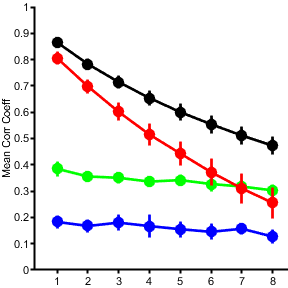


% This is mean of that number only
controlCorr1 = [con1.meanIHCCorr1,con2.meanIHCCorr1,con3.meanIHCCorr1,con4.meanIHCCorr1,con5.meanIHCCorr1,con6.meanIHCCorr1];
controlCorr2 = [con1.meanIHCCorr22,con2.meanIHCCorr22,con3.meanIHCCorr22,con4.meanIHCCorr22,con5.meanIHCCorr22,con6.meanIHCCorr22];
controlCorr3 = [con1.meanIHCCorr32,con2.meanIHCCorr32,con3.meanIHCCorr32,con4.meanIHCCorr32,con5.meanIHCCorr32,con6.meanIHCCorr32];
controlCorr4 = [con1.meanIHCCorr42,con2.meanIHCCorr42,con3.meanIHCCorr42,con4.meanIHCCorr42,con5.meanIHCCorr42,con6.meanIHCCorr42];
controlCorr5 = [con1.meanIHCCorr52,con2.meanIHCCorr52,con3.meanIHCCorr52,con4.meanIHCCorr52,con5.meanIHCCorr52,con6.meanIHCCorr52];
controlCorr6 = [con1.meanIHCCorr62,con2.meanIHCCorr62,con3.meanIHCCorr62,con4.meanIHCCorr62,con5.meanIHCCorr62,con6.meanIHCCorr62];
controlCorr7 = [con1.meanIHCCorr72,con2.meanIHCCorr72,con3.meanIHCCorr72,con4.meanIHCCorr72,con5.meanIHCCorr72,con6.meanIHCCorr72];
controlCorr8 = [con1.meanIHCCorr82,con2.meanIHCCorr82,con3.meanIHCCorr82,con4.meanIHCCorr82,con5.meanIHCCorr82,con6.meanIHCCorr82];

cx26Corr1 = [tectacx1.meanIHCCorr1,tectacx2.meanIHCCorr1,tectacx3.meanIHCCorr1,tectacx4.meanIHCCorr1,tectacx5.meanIHCCorr1];
cx26Corr2 = [tectacx1.meanIHCCorr22,tectacx2.meanIHCCorr22,tectacx3.meanIHCCorr22,tectacx4.meanIHCCorr22,tectacx5.meanIHCCorr22];
cx26Corr3 = [tectacx1.meanIHCCorr32,tectacx2.meanIHCCorr32,tectacx3.meanIHCCorr32,tectacx4.meanIHCCorr32,tectacx5.meanIHCCorr32];
cx26Corr4 = [tectacx1.meanIHCCorr42,tectacx2.meanIHCCorr42,tectacx3.meanIHCCorr42,tectacx4.meanIHCCorr42,tectacx5.meanIHCCorr42];
cx26Corr5 = [tectacx1.meanIHCCorr52,tectacx2.meanIHCCorr52,tectacx3.meanIHCCorr52,tectacx4.meanIHCCorr52,tectacx5.meanIHCCorr52];
cx26Corr6 = [tectacx1.meanIHCCorr62,tectacx2.meanIHCCorr62,tectacx3.meanIHCCorr62,tectacx4.meanIHCCorr62,tectacx5.meanIHCCorr62];
cx26Corr7 = [tectacx1.meanIHCCorr72,tectacx2.meanIHCCorr72,tectacx3.meanIHCCorr72,tectacx4.meanIHCCorr72,tectacx5.meanIHCCorr72];
cx26Corr8 = [tectacx1.meanIHCCorr82,tectacx2.meanIHCCorr82,tectacx3.meanIHCCorr82,tectacx4.meanIHCCorr82,tectacx5.meanIHCCorr82];

% scrambled matrix

% Controls have higher scrambled levels - much more correlated from distal cells 
controlCorr1s = [con1.meanIHCCorr1S,con2.meanIHCCorr1S,con3.meanIHCCorr1S,con4.meanIHCCorr1S,con5.meanIHCCorr1S,con6.meanIHCCorr1S];
controlCorr2s = [con1.meanIHCCorr2S,con2.meanIHCCorr2S,con3.meanIHCCorr2S,con4.meanIHCCorr2S,con5.meanIHCCorr2S,con6.meanIHCCorr2S];
controlCorr3s = [con1.meanIHCCorr3S,con2.meanIHCCorr3S,con3.meanIHCCorr3S,con4.meanIHCCorr3S,con5.meanIHCCorr3S,con6.meanIHCCorr3S];
controlCorr4s = [con1.meanIHCCorr4S,con2.meanIHCCorr4S,con3.meanIHCCorr4S,con4.meanIHCCorr4S,con5.meanIHCCorr4S,con6.meanIHCCorr4S];
controlCorr5s = [con1.meanIHCCorr5S,con2.meanIHCCorr5S,con3.meanIHCCorr5S,con4.meanIHCCorr5S,con5.meanIHCCorr5S,con6.meanIHCCorr5S];
controlCorr6s = [con1.meanIHCCorr6S,con2.meanIHCCorr6S,con3.meanIHCCorr6S,con4.meanIHCCorr6S,con5.meanIHCCorr6S,con6.meanIHCCorr6S];
controlCorr7s = [con1.meanIHCCorr7S,con2.meanIHCCorr7S,con3.meanIHCCorr7S,con4.meanIHCCorr7S,con5.meanIHCCorr7S,con6.meanIHCCorr7S];
controlCorr8s = [con1.meanIHCCorr8S,con2.meanIHCCorr8S,con3.meanIHCCorr8S,con4.meanIHCCorr8S,con5.meanIHCCorr8S,con6.meanIHCCorr8S];

cx26Corr1s = [tectacx1.meanIHCCorr1S,tectacx2.meanIHCCorr1S,tectacx3.meanIHCCorr1S,tectacx4.meanIHCCorr1S,tectacx5.meanIHCCorr1S];
cx26Corr2s = [tectacx1.meanIHCCorr2S,tectacx2.meanIHCCorr2S,tectacx3.meanIHCCorr2S,tectacx4.meanIHCCorr2S,tectacx5.meanIHCCorr2S];
cx26Corr3s = [tectacx1.meanIHCCorr3S,tectacx2.meanIHCCorr3S,tectacx3.meanIHCCorr3S,tectacx4.meanIHCCorr3S,tectacx5.meanIHCCorr3S];
cx26Corr4s = [tectacx1.meanIHCCorr4S,tectacx2.meanIHCCorr4S,tectacx3.meanIHCCorr4S,tectacx4.meanIHCCorr4S,tectacx5.meanIHCCorr4S];
cx26Corr5s = [tectacx1.meanIHCCorr5S,tectacx2.meanIHCCorr5S,tectacx3.meanIHCCorr5S,tectacx4.meanIHCCorr5S,tectacx5.meanIHCCorr5S];
cx26Corr6s = [tectacx1.meanIHCCorr6S,tectacx2.meanIHCCorr6S,tectacx3.meanIHCCorr6S,tectacx4.meanIHCCorr6S,tectacx5.meanIHCCorr6S];
cx26Corr7s = [tectacx1.meanIHCCorr7S,tectacx2.meanIHCCorr7S,tectacx3.meanIHCCorr7S,tectacx4.meanIHCCorr7S,tectacx5.meanIHCCorr7S];
cx26Corr8s = [tectacx1.meanIHCCorr8S,tectacx2.meanIHCCorr8S,tectacx3.meanIHCCorr8S,tectacx4.meanIHCCorr8S,tectacx5.meanIHCCorr8S];


figure
hold on
conditions = {'1','2','3','4','5','6','7','8'};
ylbl1 = 'Mean Corr Coeff';
dim = [3 3];
color1 = 'k';
color2 = 'r';
color3 = 'b';
color4 = 'g';
markSz = [27 30];


compare8(controlCorr1,controlCorr2,controlCorr3,controlCorr4,controlCorr5,controlCorr6,controlCorr7,controlCorr8,conditions,ylbl1,dim,markSz,color1)
compare8(controlCorr1s,controlCorr2s,controlCorr3s,controlCorr4s,controlCorr5s,controlCorr6s,controlCorr7s,controlCorr8s,conditions,ylbl1,dim,markSz,color4)
compare8(cx26Corr1,cx26Corr2,cx26Corr3,cx26Corr4,cx26Corr5,cx26Corr6,cx26Corr7,cx26Corr8,conditions,ylbl1,dim,markSz,color2)
compare8(cx26Corr1s,cx26Corr2s,cx26Corr3s,cx26Corr4s,cx26Corr5s,cx26Corr6s,cx26Corr7s,cx26Corr8s,conditions,ylbl1,dim,markSz,color3)

% generate mean correlation matrix
% 52 ROI is the smallest # of hair cells in all preps

ConCor1 = corr(con1.ROIdF(:,1:52));
size(con1.ROIdF)

ans =         1250          67


ConCor2 = corr(con2.ROIdF(:,1:52));
size(con2.ROIdF)

ans =         1250          52


ConCor3 = corr(con3.ROIdF(:,1:52));
size(con3.ROIdF)

ans =         1250          56


ConCor4 = corr(con4.ROIdF(:,1:52));
size(con4.ROIdF)

ans =         1250          56


ConCor5 = corr(con5.ROIdF(:,1:52));
size(con5.ROIdF)

ans =         1250          58


ConCor6 = corr(con6.ROIdF(:,1:52));
size(con6.ROIdF)

ans =         1250          63


ConCor7 = corr(con7.ROIdF(:,1:52));
size(con7.ROIdF)

ans =         1250          69


ConCor8 = corr(con8.ROIdF(:,1:52));
size(con8.ROIdF)

ans =         1250          58



Cx26Cor1 = corr(tectacx1.ROIdF(:,1:52));
size(tectacx1.ROIdF)

ans =         1250          61


Cx26Cor2 = corr(tectacx2.ROIdF(:,1:52));
size(tectacx2.ROIdF)

ans =         1250          60


Cx26Cor3 = corr(tectacx3.ROIdF(:,1:52));
size(tectacx3.ROIdF)

ans =         1250          58


Cx26Cor4 = corr(tectacx4.ROIdF(:,1:52));
size(tectacx4.ROIdF)

ans =         1250          60


Cx26Cor5 = corr(tectacx5.ROIdF(:,1:52));
size(tectacx5.ROIdF)

ans =         1250          64


Cx26Cor6 = corr(tectacx6.ROIdF(:,1:52));
size(tectacx6.ROIdF)

ans =         1250          58


Cx26Cor7 = corr(tectacx7.ROIdF(:,1:52));
size(tectacx7.ROIdF)

ans =         1250          59



% mean matrix
conMeanCorr = (ConCor1+ConCor2+ConCor3+ConCor4+ConCor5+ConCor6+ConCor7+ConCor8)/8

conMeanCorr =     1.0000    0.8629    0.8060    0.7593    0.7025    0.6369    0.6039    0.6030    0.5314    0.5453    0.4765    0.4653    0.4639    0.4228    0.4047    0.3394    0.3417    0.3347    0.3460    0.3274    0.2815    0.2802    0.2619    0.2687    0.2572    0.2257    0.2702    0.2062    0.2292    0.2364    0.2061    0.1936    0.1372    0.1448    0.1465    0.0953    0.0770    0.0645    0.0376    0.0737    0.0573    0.0837    0.0999    0.0533    0.0296    0.0375    0.0398    0.0510    0.0583    0.0568
    0.8629    1.0000    0.8920    0.8279    0.7704    0.6757    0.6313    0.6419    0.5606    0.5649    0.5107    0.5236    0.5127    0.4673    0.4470    0.3769    0.3781    0.3748    0.3812    0.3609    0.2923    0.3022    0.2875    0.2961    0.2724    0.2415    0.2840    0.2557    0.2449    0.2874    0.2406    0.2139    0.1822    0.1816    0.1710    0.1416    0.1217    0.0912    0.0460    0.0745    0.0807    0.1128    0.1232    0.0777    0.0543    0.0683    0.0678    0.0823    0

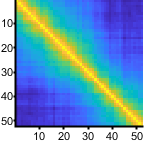

figure;
imagesc(conMeanCorr)
figQuality(gcf,gca,[1.5 1.5])

%hmo = HeatMap(conMeanCorr,'Colormap',parula,'Symmetric',false);

Cx26MeanCorr = (Cx26Cor1+Cx26Cor2+Cx26Cor3+Cx26Cor4+Cx26Cor5+Cx26Cor6+Cx26Cor7)/7

Cx26MeanCorr =     1.0000    0.7414    0.6830    0.6551    0.6557    0.5743    0.4940    0.4215    0.4230    0.3503    0.2899    0.2627    0.1972    0.1584    0.1264    0.1295    0.0865    0.0427    0.0716    0.0876    0.0455    0.0579    0.0878    0.0876    0.0658    0.0759    0.0711   -0.0013    0.0077    0.0156    0.0275   -0.0054    0.0131    0.0069    0.0490    0.0214    0.0330    0.0252    0.0470    0.0069    0.0083    0.0350   -0.0026   -0.0013   -0.0120   -0.0295    0.0236    0.0323   -0.0154   -0.0002
    0.7414    1.0000    0.7629    0.6969    0.6797    0.6015    0.5122    0.4625    0.4213    0.3382    0.3043    0.2644    0.2113    0.1842    0.1515    0.1606    0.0965    0.0616    0.1293    0.0900    0.0797    0.0646    0.0838    0.0957    0.0771    0.0917    0.1029    0.0469    0.0201    0.0539    0.0742    0.0491    0.0389    0.0274    0.0571    0.0561    0.0659    0.0579    0.0526    0.0086   -0.0194    0.0073   -0.0179   -0.0359   -0.0158   -0.0224   -0.0316   -0.0052   -

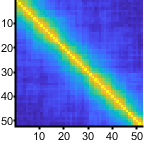

figure;
imagesc(Cx26MeanCorr)
figQuality(gcf,gca,[1.5 1.5])

%hmo = HeatMap(Cx26MeanCorr,'Colormap',parula,'Symmetric',false);

% statistics to compare heat maps ?? 

% 80th percentile correlation coefficient 

ConCor1 = corr(con1.ROIdF(:,:));
meanConCor1 = prctile(ConCor1,80,'all'); 
ConCor2 = corr(con2.ROIdF(:,:));
meanConCor2 = prctile(ConCor2,80,'all'); 
ConCor3 = corr(con3.ROIdF(:,:));
meanConCor3 = prctile(ConCor3,80,'all'); 
ConCor4 = corr(con4.ROIdF(:,:));
meanConCor4 = prctile(ConCor4,80,'all'); 
ConCor5 = corr(con5.ROIdF(:,:));
meanConCor5 = prctile(ConCor5,80,'all'); 
ConCor6 = corr(con6.ROIdF(:,:));
meanConCor6 = prctile(ConCor6,80,'all'); 
ConCor7 = corr(con7.ROIdF(:,:));
meanConCor7 = prctile(ConCor7,80,'all'); 
ConCor8 = corr(con8.ROIdF(:,:));
meanConCor8 = prctile(ConCor8,80,'all'); 

Cx26Cor1 = corr(tectacx1.ROIdF(:,:));
meanCx26Cor1 = prctile(Cx26Cor1,80,'all'); 
Cx26Cor2 = corr(tectacx2.ROIdF(:,:));
meanCx26Cor2 = prctile(Cx26Cor2,80,'all'); 
Cx26Cor3 = corr(tectacx3.ROIdF(:,:));
meanCx26Cor3 = prctile(Cx26Cor3,80,'all'); 
Cx26Cor4 = corr(tectacx4.ROIdF(:,:));
meanCx26Cor4 = prctile(Cx26Cor4,80,'all'); 
Cx26Cor5 = corr(tectacx5.ROIdF(:,:));
meanCx26Cor5 = prctile(Cx26Cor5,80,'all'); 
Cx26Cor6 = corr(tectacx6.ROIdF(:,:));
meanCx26Cor6 = prctile(Cx26Cor6,80,'all'); 
Cx26Cor7 = corr(tectacx7.ROIdF(:,:));
meanCx26Cor7 = prctile(Cx26Cor7,80,'all'); 

conCor = [meanConCor1,meanConCor2,meanConCor3,meanConCor4,meanConCor5,meanConCor6,meanConCor7,meanConCor8]

conCor =     0.6011    0.5360    0.6986    0.7010    0.6538    0.6554    0.6512    0.4203


Cx26Cor = [meanCx26Cor1,meanCx26Cor2,meanCx26Cor3,meanCx26Cor4,meanCx26Cor5,meanCx26Cor6,meanCx26Cor7]

Cx26Cor =     0.3099    0.3543    0.4130    0.4106    0.6038    0.4519    0.5436



ylbl1 = 'Correlation coefficient';
[fig5 h p1] = compare2(conCor,Cx26Cor,conditions,ylbl1,dim);

     1



p1

p1 = 0.0048

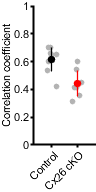

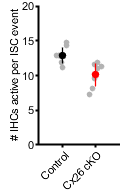

ylim([0 1])

subP = handleTheSubplot({fig3,fig5,fig5,fig5},[1 4]);

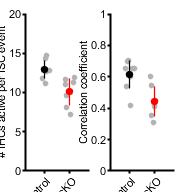

figQuality(subP,gca,[4 2])